Consider the following dynamical system


$$m\ddot{x}_1+c_1\dot{x}_1+x_1+b_1x_1x_2+x_1^3+x_1x_2^2=0,\\
m\ddot{x}_2+c_2\dot{x}_2+2x_2+x_1^2+b_2x_1x_2^2+1.6x_2^3=0.$$


with $c_1=c_2=2\zeta\sqrt{m}$. We calculate the senstivity of the SSM with respect to the parameters $\{m,b_1,b_2\}$. The nominal values of these parameters are $m=0.5, b_1=1$ and $b_2=0.3$. We take $\zeta=0.01$ in the following computations.

### Create dynamical model

clear all;
m = 0.5; b1 = 1; b2 = 0.3; zeta=0.01; Om = 1.4;
[mass,damp,stiff,fnl,fext,DM,DK,dfnl2,dfnl3,dfext] = build_model_sens_direct(m,b1,b2,zeta);
DS = DynamicalSystem();
set(DS,'M',mass,'C',damp,'K',stiff,'fnl_semi',fnl);
set(DS.Options,'Emax',1,'Nmax',2)
set(DS,'DM',DM,'DK',DK);
set(DS,'al',@(x) 2*0.01*x,'be',@(x) 0,'dal',@(x) 2*0.01,'dbe',@(x) 0);
set(DS,'Dfnl2_semi',dfnl2,'Dfnl3_semi',dfnl3);
set(DS,'fext',fext,'Omega',Om,'dfext',dfext);
[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0141 + 1.4141i
  -0.0141 - 1.4141i



### SSM computation - explicit computation

S = SSM(DS);
resonant_modes = [1 2]; % choose master spectral subspace
S.choose_E(resonant_modes);

sigma_out = 0
sigma_in = 1


order = 3; % SSM expansion order
[We,Re] = S.explicit_whisker();


 second order explict solution 


### SSM computation - via SSMTool parameterization

[W_0,R_0,W_1,R_1] = ssmtool_comp(m,b1,b2,zeta,Om);

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0141 + 1.4141i
  -0.0141 - 1.4141i

sigma_out = 0
sigma_in = 1
Computing autonomous whisker at order 2
0 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:01
Estimated memory usage at order  2 = 6.87E-03 MB
Computing autonomous whisker at order 3
6 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.10E-02 MB


### SSM computation - $\gamma$ via adjoint method

dr21_adj = S.adjoint_sentivity(We.W20,We.W11,We.W30,We.W21,Re.r21);


 damping ratio is 1.000000e-02


### SSM senstivity computation

% set(S.Options,'solver','backslash');
[DW,DR] = S.explicit_senstivity_whisker(We,Re);


 damping ratio is 1.000000e-02


### Analytic solutions - SSM and its sensitivity

[Wa,Ra,DWa,DRa] = ana_solutions(m,b1,zeta,b2,Om);

### Comparison of SSM results 

#### Analytic solution and SSMTool solution - validate derivation

fprintf('\n difference in terms of W10 \n')


 difference in terms of W10 


norm(Wa.W10-full(W_0(1).coeffs(:,2)))/norm(Wa.W10)

ans = 1.8130e-16

fprintf('\n difference in terms of W20 \n')


 difference in terms of W20 


norm(Wa.W20-full(W_0(2).coeffs(:,3)))/norm(Wa.W20)

ans = 5.3381e-16

fprintf('\n difference in terms of W11 \n')


 difference in terms of W11 


norm(Wa.W11-full(W_0(2).coeffs(:,2)))/norm(Wa.W11)

ans = 4.4391e-16

fprintf('\n difference in terms of W30 \n')


 difference in terms of W30 


norm(Wa.W30-full(W_0(3).coeffs(:,4)))/norm(Wa.W30)

ans = 5.8456e-16

fprintf('\n difference in terms of W21 \n')


 difference in terms of W21 


norm(Wa.W21-full(W_0(3).coeffs(:,3)))/norm(Wa.W21)

ans = 4.4638e-13

fprintf('\n difference in terms of x0 \n')


 difference in terms of x0 


W_1(2).kappa

ans = 1

norm(Wa.x0-W_1(2).W.coeffs)/norm(Wa.x0)

ans = 2.6312e-15

fprintf('\n difference in terms of gamma \n')


 difference in terms of gamma 


abs(Ra.gamma-full(R_0(3).coeffs(1,2)))/abs(Ra.gamma)

ans = 2.5124e-16

fprintf('\n difference in terms of ftilde \n')


 difference in terms of ftilde 


abs(Ra.ftilde-R_1(2).R.coeffs(1))/abs(Ra.ftilde)

ans = 2.2203e-16

#### Explicit solution and analytic solution - validate code implementation

fprintf('\n difference in terms of W10 \n')


 difference in terms of W10 


We.W10-Wa.W10

ans = 1.0e-15 *

   0.2220 + 0.0000i
   0.0000 + 0.0000i
  -0.0069 + 0.6661i
   0.0000 + 0.0000i


fprintf('\n difference in terms of W20 \n')


 difference in terms of W20 


We.W20-Wa.W20

ans = 1.0e-15 *

   0.0000 + 0.0000i
  -0.4441 + 0.0104i
   0.0000 + 0.0000i
  -0.0173 - 0.8882i


fprintf('\n difference in terms of W11 \n')


 difference in terms of W11 


We.W11-Wa.W11

ans = 1.0e-15 *

         0
   -0.4441
         0
    0.0278


fprintf('\n difference in terms of W30 \n')


 difference in terms of W30 


We.W30-Wa.W30

ans = 1.0e-15 *

  -0.2220 + 0.0035i
   0.0000 + 0.0000i
   0.0000 - 0.4441i
   0.0000 + 0.0000i


fprintf('\n difference in terms of W21 \n')


 difference in terms of W21 


We.W21-Wa.W21

ans = 1.0e-11 *

   0.1465 + 0.0057i
   0.0000 + 0.0000i
  -0.0142 + 0.2071i
   0.0000 + 0.0000i


fprintf('\n difference in terms of x0 \n')


 difference in terms of x0 


We.x0-Wa.x0

ans = 1.0e-15 *

   0.8882 - 0.9165i
  -0.0278 + 0.0000i
   0.4501 + 0.4441i
   0.0009 - 0.0278i


fprintf('\n difference in terms of gamma \n')


 difference in terms of gamma 


Re.r21-Ra.gamma

ans = -6.9389e-18

fprintf('\n difference in terms of ftilde \n')


 difference in terms of ftilde 


Re.ftilde-Ra.ftilde

ans = 0.0000e+00 + 2.7756e-17i

### Compare results - sensitivity of SSM

#### Direct computation and analytic results

fprintf('\n difference in terms of dW10 \n')


 difference in terms of dW10 


dw10res = DW.DW10-DWa.DW10

dw10res = 1.0e-14 *

  -0.0444 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0021 - 0.1332i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


sqrt(sum(dw10res.*dw10res))./sqrt(sum(DWa.DW10.*DWa.DW10)) % relative difference

ans = 1.0e-15 *

   0.3357 + 0.0021i      NaN + 0.0000i      NaN + 0.0000i


fprintf('\n difference in terms of dW20 \n')


 difference in terms of dW20 


dw20res = DW.DW20-DWa.DW20

dw20res = 1.0e-14 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.1110 - 0.0042i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0097 + 0.3553i   0.0000 + 0.0000i   0.0000 + 0.0000i


sqrt(sum(dw20res.*dw20res))./sqrt(sum(DWa.DW20.*DWa.DW20)) % relative difference

ans = 1.0e-15 *

   0.4093 - 0.0069i      NaN + 0.0000i      NaN + 0.0000i


fprintf('\n difference in terms of dW11 \n')


 difference in terms of dW11 


dw11res = DW.DW11-DWa.DW11

dw11res = 1.0e-14 *

         0         0         0
    0.1776         0         0
         0         0         0
   -0.0139         0         0


sqrt(sum(dw11res.*dw11res))./sqrt(sum(DWa.DW11.*DWa.DW11)) % relative difference

ans = 1.0e-15 *

    0.4450       NaN       NaN


fprintf('\n difference in terms of dW30 \n')


 difference in terms of dW30 


dw30res = DW.DW30-DWa.DW30

dw30res = 1.0e-14 *

   0.0222 + 0.0007i  -0.0167 + 0.0006i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0069 + 0.1776i  -0.0014 - 0.0555i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


sqrt(sum(dw30res.*dw30res))./sqrt(sum(DWa.DW30.*DWa.DW30)) % relative difference

ans = 1.0e-15 *

  -0.1989 - 0.0101i   0.7267 + 0.0004i      NaN + 0.0000i


fprintf('\n difference in terms of dW21 \n')


 difference in terms of dW21 


dw21res = DW.DW21-DWa.DW21

dw21res = 1.0e-10 *

  -0.0569 - 0.0026i  -0.0029 - 0.0001i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0080 - 0.1006i   0.0004 - 0.0041i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


sqrt(sum(dw21res.*dw21res))./sqrt(sum(DWa.DW21.*DWa.DW21)) % relative difference

ans = 1.0e-12 *

  -0.9757 - 0.1204i  -0.8199 - 0.1302i      NaN + 0.0000i


fprintf('\n difference in terms of dx0 \n')


 difference in terms of dx0 


dx0res = DW.Dx0-DWa.Dx0

dx0res = 1.0e-13 *

   0.0693 - 0.9753i   0.0194 - 0.0198i   0.0601 - 0.0611i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.5333 + 0.0824i   0.0277 + 0.0275i   0.0856 + 0.0854i
   0.0000 + 0.0011i   0.0000 + 0.0006i   0.0001 + 0.0022i


sqrt(sum(dx0res.*dx0res))./sqrt(sum(DWa.Dx0.*DWa.Dx0)) % relative difference

ans = 1.0e-12 *

  -0.3088 - 0.0278i   0.0138 - 0.0132i   0.0129 - 0.0122i


fprintf('\n difference in terms of dgamma \n')


 difference in terms of dgamma 


DR.Dr21-DRa.Dgamma

ans = 1.0e-14 *

   0.0007 - 0.5329i
  -0.0007 - 0.0555i
   0.0000 + 0.0000i


fprintf('\n difference in terms of dftilde \n')


 difference in terms of dftilde 


DR.Dftilde-DRa.Dftilde

ans = 1.0e-15 *

   0.0000 + 0.1110i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


#### Adjoint analysis and analytic results

dr21_adj-DRa.Dgamma

ans = 1.0e-14 *

   0.0000 - 0.7105i
  -0.0007 - 0.0555i
   0.0000 + 0.0000i


#### Curvature of SSM

% calculate curvature
Curv = Wa.W20'*Wa.W20+Wa.W11'*Wa.W11

Curv = 13.0032

% derivatives of curvature
DCurv = 2*real(Wa.W20'*DWa.DW20)+2*(Wa.W11'*DWa.DW11)

DCurv =   -68.0192         0         0


### Perturbed SSMs

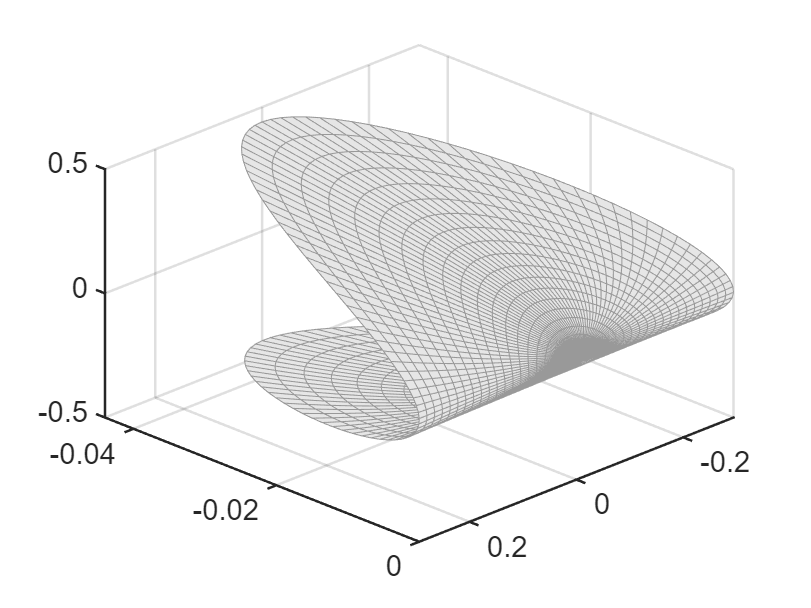

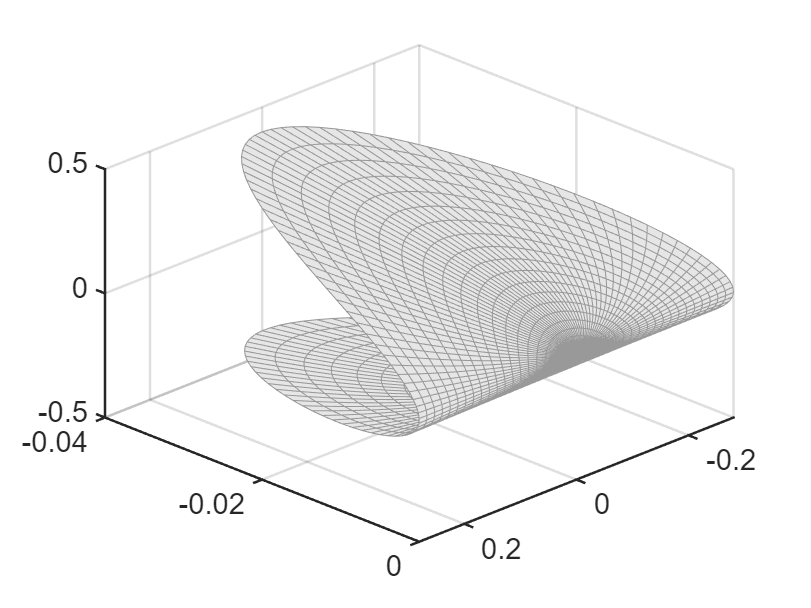

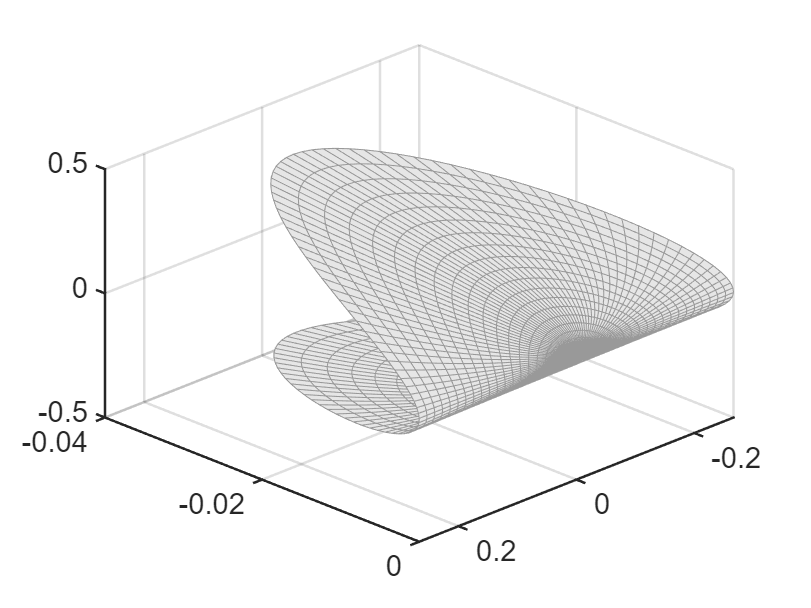

rhosamp = linspace(0,0.1,21); plotdof = [1 2 3]; 
pidx = 1; pfracs = [-0.1 0 0.1]*m;
% pidx = 2; pfracs = [-10 0 10]*b1;
% pidx = 3; pfracs = [-10 0 10]*b2;
zmesh = S.SSM_sensitivity(We,DW,rhosamp,plotdof,pidx,pfracs);

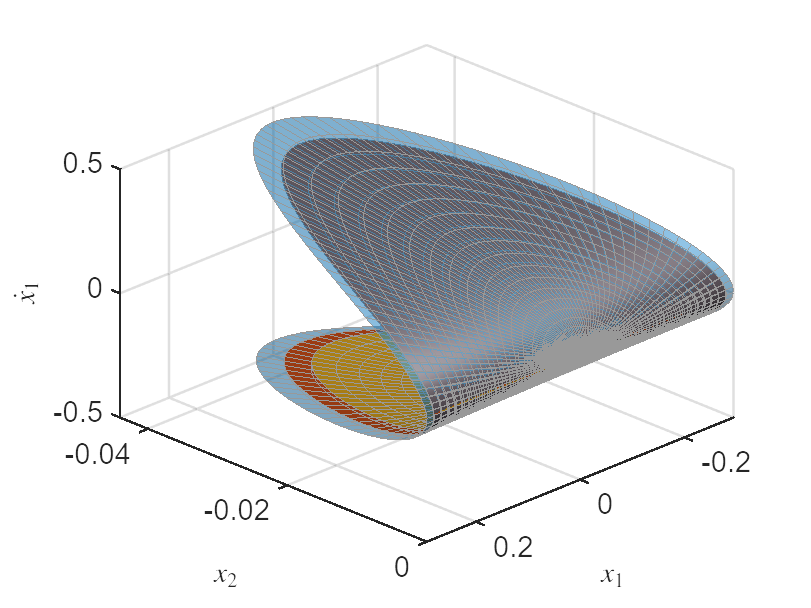

colors = get(0,'defaultaxescolororder');
figure; hold on
h = surf(zmesh{1}.zdof1,zmesh{1}.zdof2,zmesh{1}.zdof3,'FaceColor', colors(1,:), 'FaceAlpha', 0.5, ...
    'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.2);
view([1,1,1])
grid on
set(gca,'LineWidth',1.2);
set(gca,'FontSize',14);

surf(zmesh{2}.zdof1,zmesh{2}.zdof2,zmesh{2}.zdof3,'FaceColor', colors(2,:), 'FaceAlpha', 1, ...
    'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.2);
surf(zmesh{3}.zdof1,zmesh{3}.zdof2,zmesh{3}.zdof3,'FaceColor', colors(3,:), 'FaceAlpha', 1, ...
    'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.2);
camlight; lighting gouraud
xlabel('$x_1$','FontSize',14,'Interpreter','latex');
ylabel('$x_2$','FontSize',14,'Interpreter','latex');
zlabel('$\dot{x}_1$','FontSize',14,'Interpreter','latex');

### Perturbed backbone curves

outdof = [1 2];
freqRange = [1.3 1.6];
pidx   = 1; pfracs = [-0.05 0 0.05]*m;  % m 
% pidx   = 2; pfracs = [-3 0 3]*b1; % b1
% pidx   = 3; pfracs = [-30 0 30]*b1; % b2 -- not affected
pBBs = S.BB_sensitivity(We,Re,DW,DR,outdof,freqRange,pidx,pfracs);

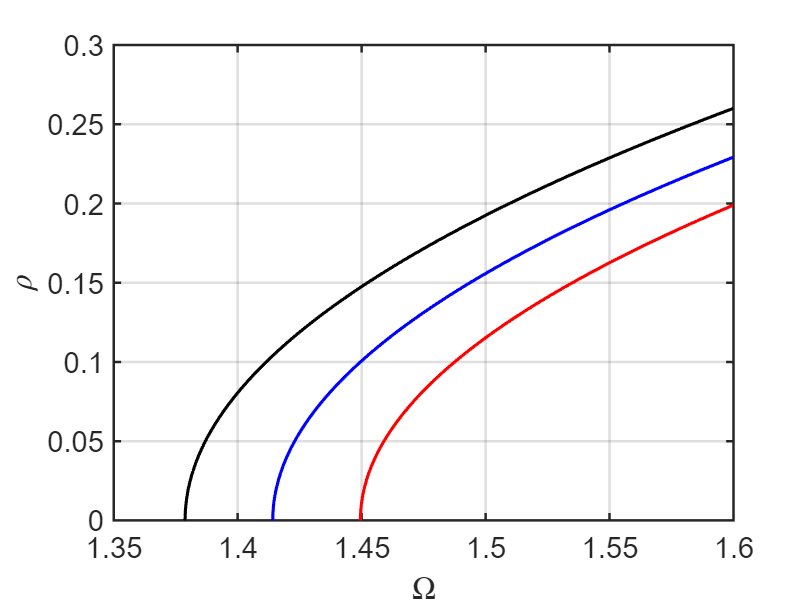

figure; hold on
plot(pBBs{1}.om,pBBs{1}.rho,'r-','LineWidth',1.5);
plot(pBBs{2}.om,pBBs{2}.rho,'b-','LineWidth',1.5)
plot(pBBs{3}.om,pBBs{3}.rho,'k-','LineWidth',1.5)
grid on; box on;
xlabel('$\Omega$','FontSize',14,'Interpreter','latex');
ylabel('$\rho$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);

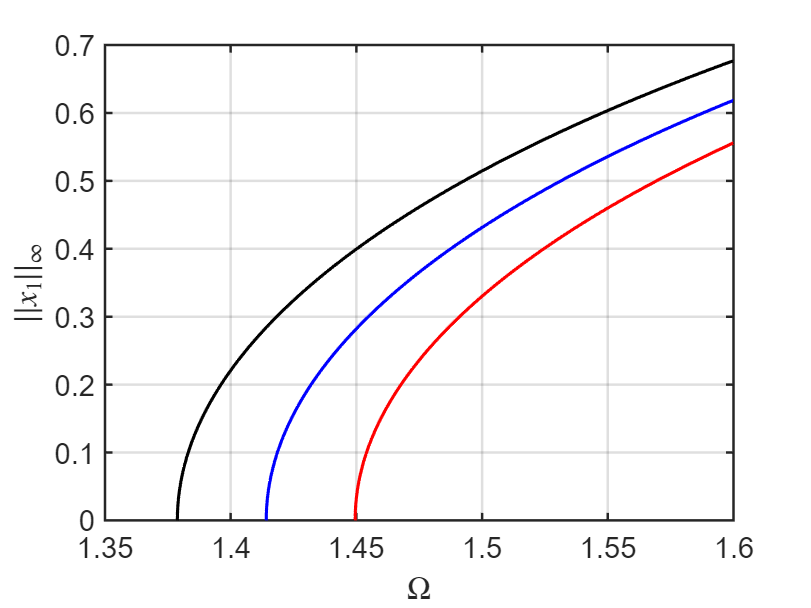

figrho = gcf;

figure; hold on
plot(pBBs{1}.om,pBBs{1}.ampLinf(1,:),'r-','LineWidth',1.5);
plot(pBBs{2}.om,pBBs{2}.ampLinf(1,:),'b-','LineWidth',1.5)
plot(pBBs{3}.om,pBBs{3}.ampLinf(1,:),'k-','LineWidth',1.5)
grid on; box on;
xlabel('$\Omega$','FontSize',14,'Interpreter','latex');
ylabel('$||x_1||_\infty$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);

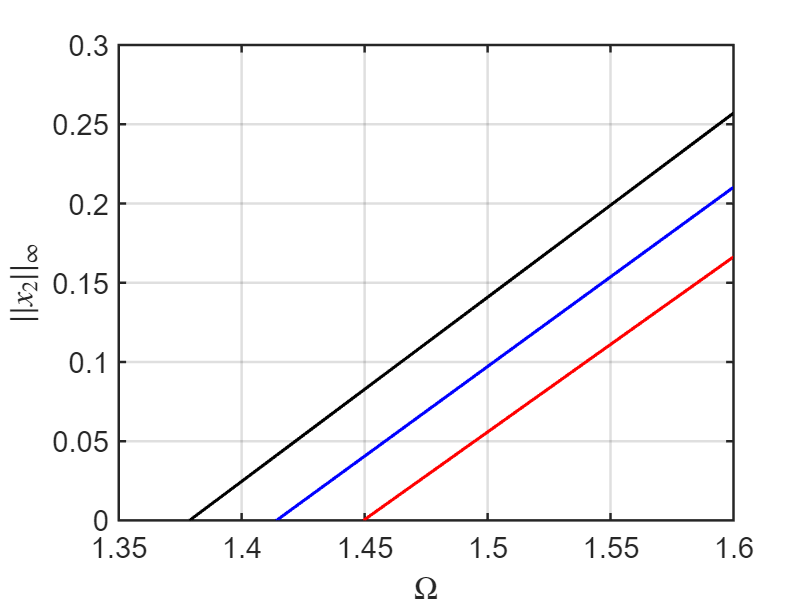

figz1 = gcf;

figure; hold on
plot(pBBs{1}.om,pBBs{1}.ampLinf(2,:),'r-','LineWidth',1.5);
plot(pBBs{2}.om,pBBs{2}.ampLinf(2,:),'b-','LineWidth',1.5)
plot(pBBs{3}.om,pBBs{3}.ampLinf(2,:),'k-','LineWidth',1.5)
grid on; box on;
xlabel('$\Omega$','FontSize',14,'Interpreter','latex');
ylabel('$||x_2||_\infty$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);

figz2 = gcf;

Direct computation - for the purpose of validation

bbp1 = comp_bb(m+pfracs(1),b1,b2,zeta,freqRange,outdof);

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0145 + 1.4509i
  -0.0145 - 1.4509i

sigma_out = 0
sigma_in = 1

 second order explict solution 

 damping ratio is 1.000000e-02


bbp3 = comp_bb(m+pfracs(3),b1,b2,zeta,freqRange,outdof);

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0138 + 1.3801i
  -0.0138 - 1.3801i

sigma_out = 0
sigma_in = 1

 second order explict solution 

 damping ratio is 1.000000e-02


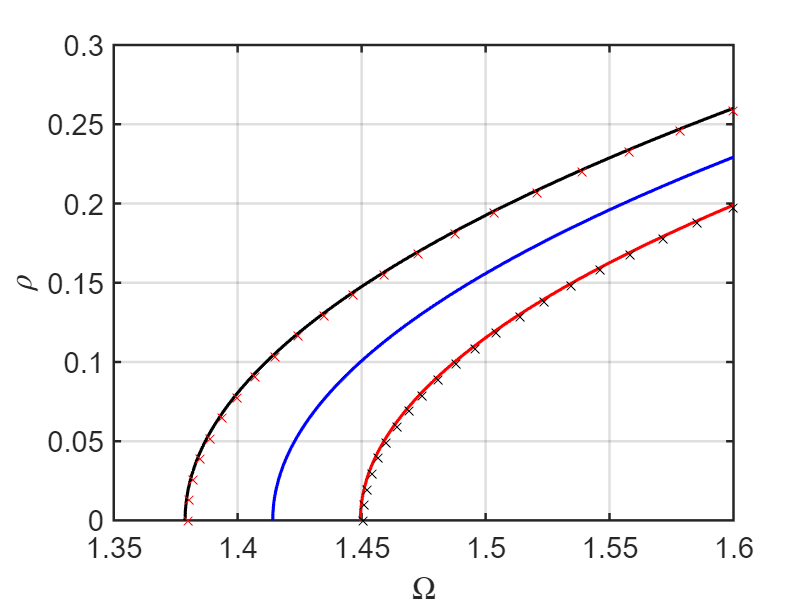

% bbp1 = comp_bb(m,b1+pfracs(1),b2,zeta,freqRange,outdof);
% bbp3 = comp_bb(m,b1+pfracs(3),b2,zeta,freqRange,outdof);
figure(figrho); hold on
plot(bbp1{1}.om(1:5:end),bbp1{1}.rho(1:5:end),'kx')
plot(bbp3{1}.om(1:5:end),bbp3{1}.rho(1:5:end),'rx')

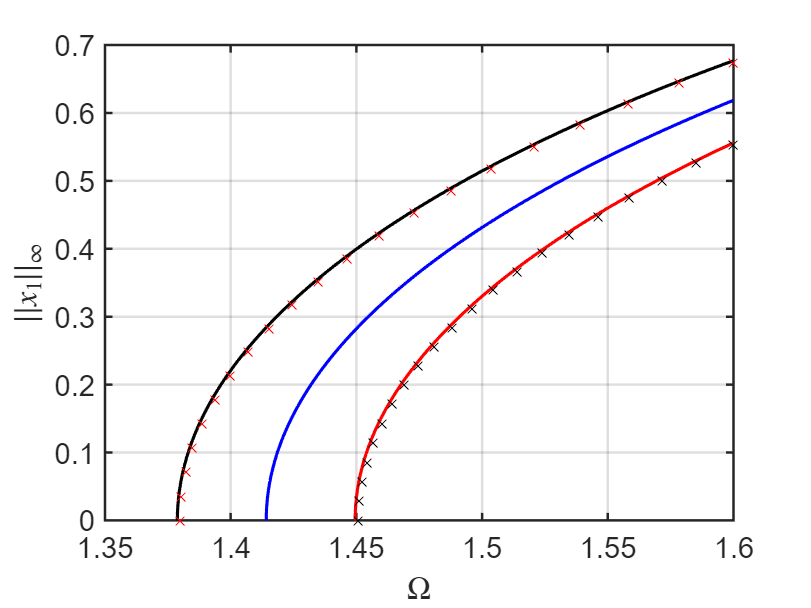

figure(figz1); hold on
plot(bbp1{1}.om(1:5:end),bbp1{1}.ampLinf(1,1:5:end),'kx')
plot(bbp3{1}.om(1:5:end),bbp3{1}.ampLinf(1,1:5:end),'rx')

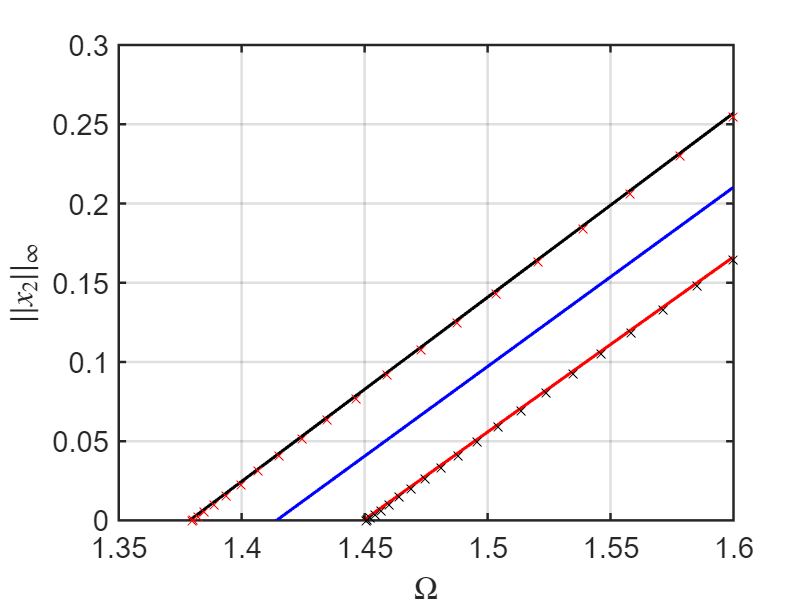

figure(figz2); hold on
plot(bbp1{1}.om(1:5:end),bbp1{1}.ampLinf(2,1:5:end),'kx')
plot(bbp3{1}.om(1:5:end),bbp3{1}.ampLinf(2,1:5:end),'rx')

## Forced vibration

### Sensitivity of forced periodic response

optdof = [1 2 3 4]; Q = eye(4); epsilon = 0.01;
[frce,dfrce] = S.po_sensitivity(We,Re,DW,DR,optdof,Q,epsilon);

### Validation via central finite difference

- with respect to $m$

dm = m*0.001;
frc_mp = comp_frc(m+dm,b1,b2,zeta,epsilon,Om);

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0141 + 1.4134i
  -0.0141 - 1.4134i

sigma_out = 0
sigma_in = 1

 second order explict solution 

 damping ratio is 1.000000e-02


frc_mm = comp_frc(m-dm,b1,b2,zeta,epsilon,Om);

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0141 + 1.4149i
  -0.0141 - 1.4149i

sigma_out = 0
sigma_in = 1

 second order explict solution 

 damping ratio is 1.000000e-02


drho_dm = (frc_mp.rho - frc_mm.rho)/(2*dm);
dth_dm  = (frc_mp.th - frc_mm.th)/(2*dm);
damp_dm = (frc_mp.amp - frc_mm.amp)/(2*dm);
drhomax_dm = (frc_mp.rhomax-frc_mm.rhomax)/(2*dm);
dommax_dm  = (frc_mp.Ommax-frc_mm.Ommax)/(2*dm);
% calculate derivatives
fprintf('relative error for drho_dm is %d\n', abs((dfrce.Drho(1)-drho_dm)/dfrce.Drho(1))); 

relative error for drho_dm is 7.166348e-05


fprintf('relative error for dth_dm is %d\n', abs((dfrce.Dth(1)-dth_dm)/dfrce.Dth(1))); 

relative error for dth_dm is 3.184466e-05


fprintf('relative error for damp_dm is %d\n', abs((dfrce.Damp(1)-damp_dm)/dfrce.Damp(1)));

relative error for damp_dm is 7.725799e-05


fprintf('absolute error for drhomax_dm is %d\n', abs((dfrce.Drhomax(1)-drhomax_dm)/dfrce.Drhomax(1)));

absolute error for drhomax_dm is 2.779801e-08


fprintf('absolute error for dommax_dm is %d\n', abs((dfrce.DOmmax(1)-dommax_dm)/dfrce.DOmmax(1)));

absolute error for dommax_dm is 6.663782e-07


- with respect to $b_1$

db1     = b1*0.01;
frc_b1p = comp_frc(m,b1+db1,b2,zeta,epsilon,Om);

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0141 + 1.4141i
  -0.0141 - 1.4141i

sigma_out = 0
sigma_in = 1

 second order explict solution 

 damping ratio is 1.000000e-02


frc_b1m = comp_frc(m,b1-db1,b2,zeta,epsilon,Om);

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0141 + 1.4141i
  -0.0141 - 1.4141i

sigma_out = 0
sigma_in = 1

 second order explict solution 

 damping ratio is 1.000000e-02


drho_db1 = (frc_b1p.rho - frc_b1m.rho)/(2*db1);
dth_db1  = (frc_b1p.th - frc_b1m.th)/(2*db1);
damp_db1 = (frc_b1p.amp - frc_b1m.amp)/(2*db1);
drhomax_db1 = (frc_b1p.rhomax-frc_b1m.rhomax)/(2*db1);
dommax_db1  = (frc_b1p.Ommax-frc_b1m.Ommax)/(2*db1);
% compare derivatives
fprintf('relative error for drho_db1 is %d\n', abs((dfrce.Drho(2)-drho_db1)/dfrce.Drho(2))); 

relative error for drho_db1 is 8.252448e-07


fprintf('relative error for dth_db1 is %d\n', abs((dfrce.Dth(2)-dth_db1)/dfrce.Dth(2))); 

relative error for dth_db1 is 9.134804e-07


fprintf('relative error for damp_db1 is %d\n', abs((dfrce.Damp(2)-damp_db1)/dfrce.Damp(2)));

relative error for damp_db1 is 7.924919e-07


fprintf('relative error for drhomax_db1 is %d\n', abs((dfrce.Drhomax(2)-drhomax_db1)/dfrce.Drhomax(2)));

relative error for drhomax_db1 is 8.087896e-08


fprintf('relative error for dommax_db1 is %d\n', abs((dfrce.DOmmax(2)-dommax_db1)/dfrce.DOmmax(2)));

relative error for dommax_db1 is 4.181537e-08


- with respect to $b_2$

db2     = b2*1e-6;
frc_b2p = comp_frc(m,b1,b2+db2,zeta,epsilon,Om);

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0141 + 1.4141i
  -0.0141 - 1.4141i

sigma_out = 0
sigma_in = 1

 second order explict solution 

 damping ratio is 1.000000e-02


frc_b2m = comp_frc(m,b1,b2-db2,zeta,epsilon,Om);

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0141 + 1.4141i
  -0.0141 - 1.4141i

sigma_out = 0
sigma_in = 1

 second order explict solution 

 damping ratio is 1.000000e-02


drho_db2 = (frc_b2p.rho - frc_b2m.rho)/(2*db2);
dth_db2  = (frc_b2p.th - frc_b2m.th)/(2*db2);
damp_db2 = (frc_b2p.amp - frc_b2m.amp)/(2*db2);
drhomax_db2 = (frc_b2p.rhomax-frc_b2m.rhomax)/(2*db2);
dommax_db2  = (frc_b2p.Ommax-frc_b2m.Ommax)/(2*db2);
% calculate derivatives
fprintf('absolute error for drho_db2 is %d\n', abs(dfrce.Drho(3)-drho_db2)); 

absolute error for drho_db2 is 0


fprintf('absolute error for dth_db2 is %d\n', abs(dfrce.Dth(3)-dth_db2)); 

absolute error for dth_db2 is 0


fprintf('relative error for damp_db2 is %d\n', abs((dfrce.Damp(3)-damp_db2)/dfrce.Damp(3)));

relative error for damp_db2 is 1.186025e-07


fprintf('absolute error for drhomax_db2 is %d\n', abs(dfrce.Drhomax(3)-drhomax_db2));

absolute error for drhomax_db2 is 0


fprintf('absolute error for dommax_db2 is %d\n', abs(dfrce.DOmmax(3)-dommax_db2));

absolute error for dommax_db2 is 0


### Peturbed FRCs

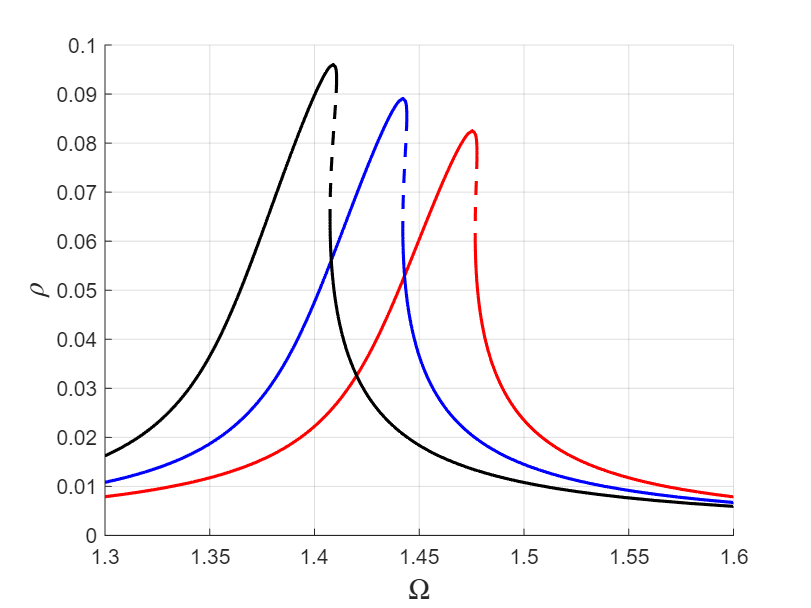

% perturbed FRC
pidx = 1; pfracs = [-0.05 0 0.05]*m;
% pidx = 2; pfracs = [-3 0 3]*b1; % b1
% pidx = 3; pfracs = [-3 0 3];
freqRange = [1.3 1.6];
pFRCs = S.FRC_sensitivity(We,Re,DW,DR,optdof,Q,epsilon,freqRange,pidx,pfracs);

ST1 = cell(2,1);
ST1{1} = {'r--','LineWidth',1.5}; % unstable
ST1{2} = {'r-','LineWidth',1.5};  % stable
ST2 = cell(2,1);
ST2{1} = {'b--','LineWidth',1.5}; % unstable
ST2{2} = {'b-','LineWidth',1.5};  % stable
ST3 = cell(2,1);
ST3{1} = {'k--','LineWidth',1.5}; % unstable
ST3{2} = {'k-','LineWidth',1.5};  % stable

figure; hold on
plot_stab_lines(pFRCs{1}.om,pFRCs{1}.rho,pFRCs{1}.st,ST1);
plot_stab_lines(pFRCs{2}.om,pFRCs{2}.rho,pFRCs{2}.st,ST2);
plot_stab_lines(pFRCs{3}.om,pFRCs{3}.rho,pFRCs{3}.st,ST3);
xlim(freqRange); grid on; 
xlabel('$\Omega$','FontSize',14,'Interpreter','latex');
ylabel('$\rho$','FontSize',14,'Interpreter','latex');

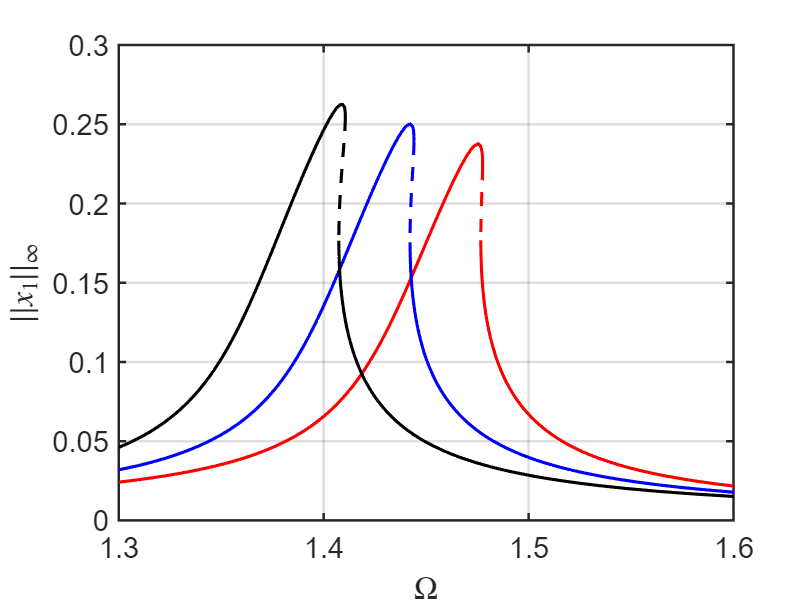

figrho = gcf;
figure; hold on
plot_stab_lines(pFRCs{1}.om,pFRCs{1}.ampLinf(1,:),pFRCs{1}.st,ST1);
plot_stab_lines(pFRCs{2}.om,pFRCs{2}.ampLinf(1,:),pFRCs{2}.st,ST2);
plot_stab_lines(pFRCs{3}.om,pFRCs{3}.ampLinf(1,:),pFRCs{3}.st,ST3);
xlim(freqRange); grid on; box on;
xlabel('$\Omega$','FontSize',14,'Interpreter','latex')
ylabel('$||x_1||_\infty$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);

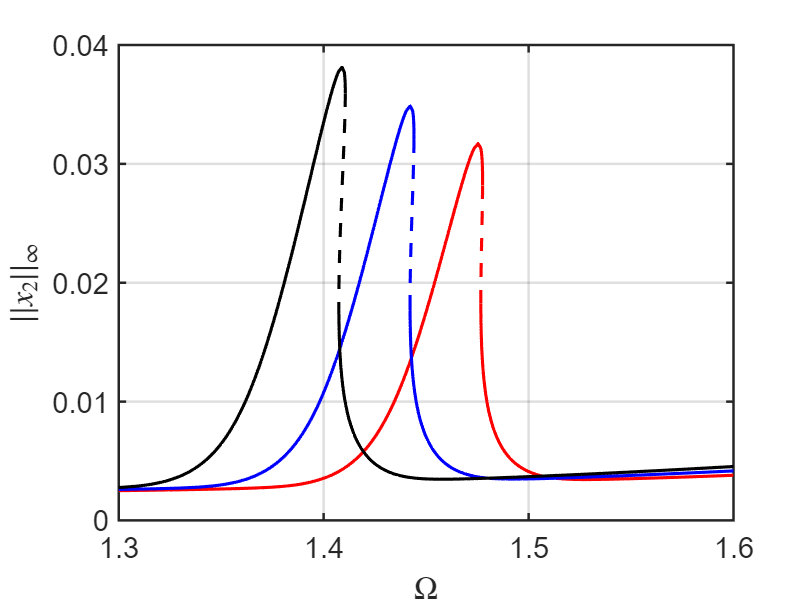

figamp1 = gcf;
figure; hold on
plot_stab_lines(pFRCs{1}.om,pFRCs{1}.ampLinf(2,:),pFRCs{1}.st,ST1);
plot_stab_lines(pFRCs{2}.om,pFRCs{2}.ampLinf(2,:),pFRCs{2}.st,ST2);
plot_stab_lines(pFRCs{3}.om,pFRCs{3}.ampLinf(2,:),pFRCs{3}.st,ST3);
xlim(freqRange); grid on; box on;
xlabel('$\Omega$','FontSize',14,'Interpreter','latex')
ylabel('$||x_2||_\infty$','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',14);
set(gca,'LineWidth',1.2);

figamp2 = gcf;

Direct computation - for the purpose of validation

[~,frcp1] = comp_frc(m+pfracs(1),b1,b2,zeta,epsilon,Om,freqRange);

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0145 + 1.4509i
  -0.0145 - 1.4509i

sigma_out = 0
sigma_in = 1

 second order explict solution 

 damping ratio is 1.000000e-02


[~,frcp3] = comp_frc(m+pfracs(3),b1,b2,zeta,epsilon,Om,freqRange);

Due to high-dimensionality, we compute only the first 1 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.000000e-02

 The first 2 eigenvalues are given as 
  -0.0138 + 1.3801i
  -0.0138 - 1.3801i

sigma_out = 0
sigma_in = 1

 second order explict solution 

 damping ratio is 1.000000e-02


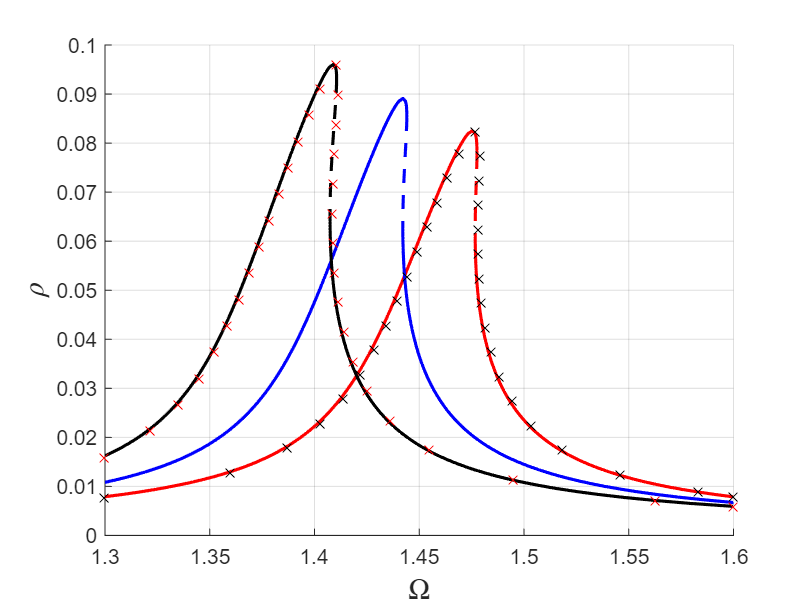

% [~,frcp1] = comp_frc(m,b1+pfracs(1),b2,zeta,epsilon,Om,freqRange);
% [~,frcp3] = comp_frc(m,b1+pfracs(3),b2,zeta,epsilon,Om,freqRange);
% [~,frcp1] = comp_frc(m,b1,b2+pfracs(1),zeta,epsilon,Om,freqRange);
% [~,frcp3] = comp_frc(m,b1,b2+pfracs(3),zeta,epsilon,Om,freqRange);
figure(figrho); hold on
nom = numel(frcp1{1}.om);
idxplot = [1:10:nom-1,nom-2,nom];
plot(frcp1{1}.om(idxplot),frcp1{1}.rho(idxplot),'kx')
plot(frcp3{1}.om(idxplot),frcp3{1}.rho(idxplot),'rx')

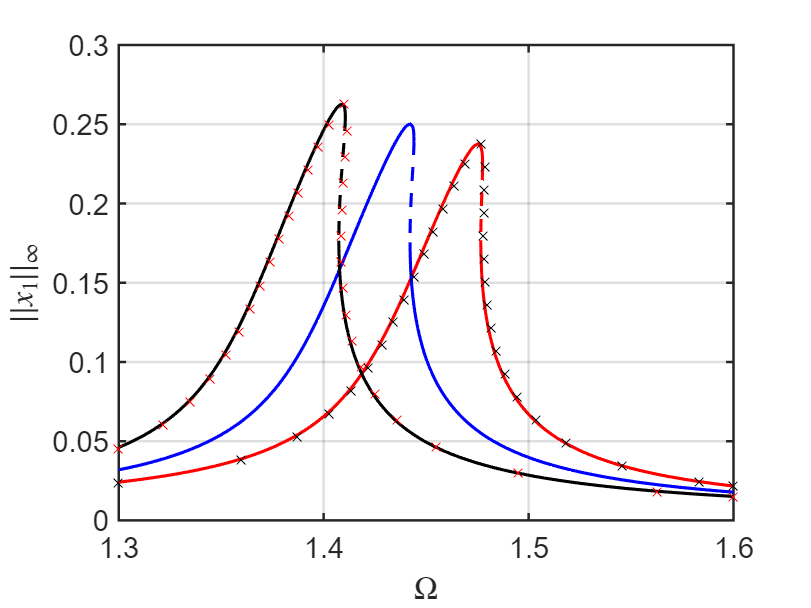

figure(figamp1); hold on
plot(frcp1{1}.om(idxplot),frcp1{1}.ampLinf(1,idxplot),'kx')
plot(frcp3{1}.om(idxplot),frcp3{1}.ampLinf(1,idxplot),'rx')

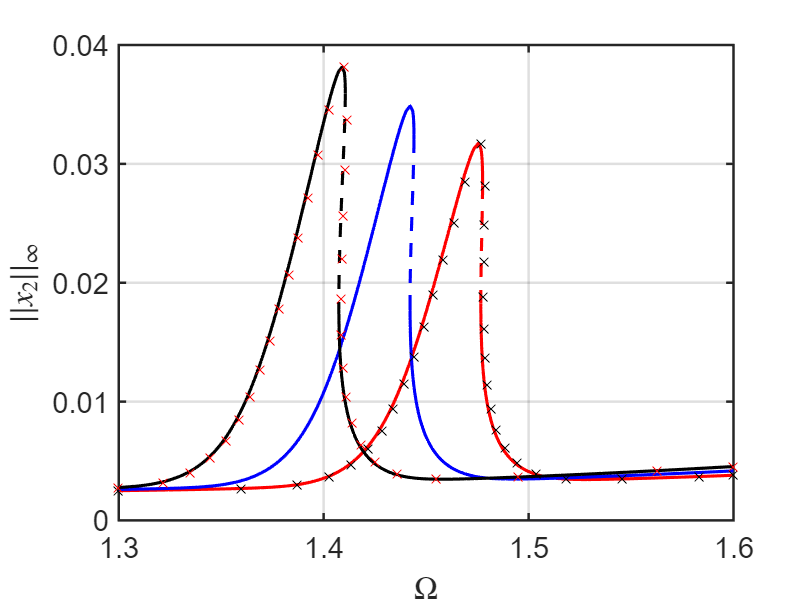

figure(figamp2); hold on
plot(frcp1{1}.om(idxplot),frcp1{1}.ampLinf(2,idxplot),'kx')
plot(frcp3{1}.om(idxplot),frcp3{1}.ampLinf(2,idxplot),'rx')

Demonstration

- Order 3 is enough

- Non-autonomous part is necessary for $x_2$

% [FRC1,FRC2,FRC3,FRC_nonauto] = ssmtool_frcs(m,b1,b2,zeta);